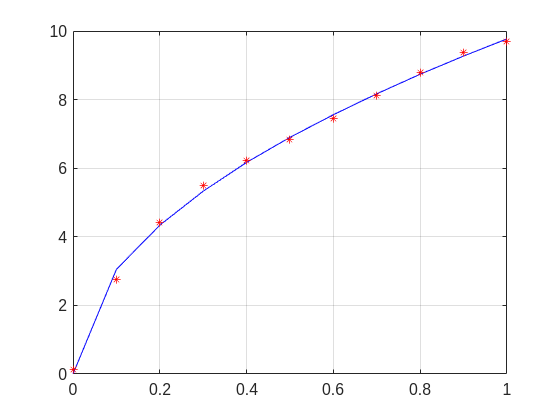

% OL Speed Data
clear
close all
thrust = linspace(0,1,11)';

speed = [0;
        3.05;
        4.34;
        5.33;
        6.17;
        6.90;
        7.56;
        8.17;
        8.74;
        9.27;
        9.77];

figure(1)
plot(thrust,speed,'b-')
grid on
hold on

p = polyfit(thrust,speed,4);
f = polyval(p,thrust);
plot(thrust,f,'r*')

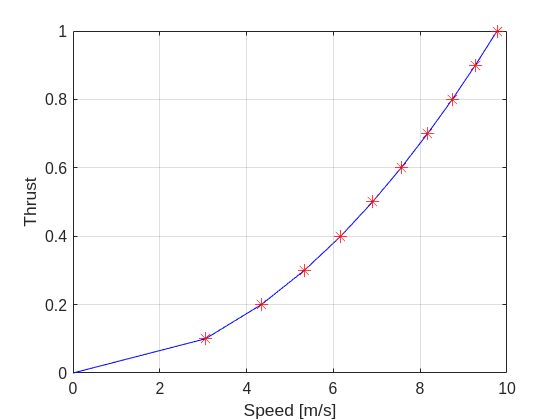


figure(2)
clf
% Set the default text sizes for the root figure
set(0,'defaulttextfontsize',20);
set(0,'defaultaxesfontsize',12);
 
% Set the background color to white
set(gcf,'color','w');

plot(speed,thrust,'b-')
grid on
hold on
q = polyfit(speed,thrust,4);
g = polyval(q,speed);
plot(speed,g,'r*','MarkerSize',10)
xlabel('Speed [m/s]')
ylabel('Thrust')
ylim([0 1])

%  export_fig figures/thesis_figs/poly.png -png -r300 -painters